clear all
clc
close all




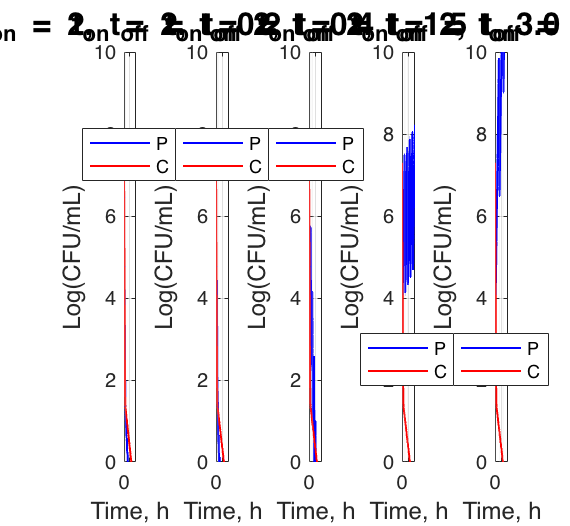


% figure position and size
set(groot,'defaultfigureposition',[120 80 285 200])

% Deifne model parameters as estimated in Figure 6 data - model fit


N0 = 7.3;% Intial cell count 


f0 = 9.5e-7;
k1 = [-.15698 -3.8498  5e-06 0];
k2 = [-1.1598 1.354  0 1.1598];

T_on = [2];
ratio = [0.2, 0.4, 1.5, 3, 5]; % t_off/t_on, T_off = T_on*ratio

m = length(T_on);
n = length(ratio);
I = m*n;
counter = 1;
for j = 1:n
    for i = 1: m
       
            t_on = T_on(i);
            t_off = T_on*ratio(j);
            t_start = 0;
            t_stop = t_on;
            t_total = 40;

            tspan = linspace(t_start,t_stop,20);
            [t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan,10.^N0*[(1-f0),f0]);
            tplot = tspan;
            y_model = log10(sum(Ns,2));
            
            while t_stop < t_total
            t_start = t_stop;
            t_stop = t_start+t_off;
            if t_stop > t_total
                t_stop = t_total;
            end
            tspan = linspace(t_start,t_stop,30);
            [t,Ns] = ode45(@(t,y)odeint(t,y,k2),tspan,[Ns(end,1), Ns(end,2)]);
            tplot = [tplot,tspan];
            y_model = [y_model;log10(sum(Ns,2))]; 
            
            if t_stop < t_total
                t_start = t_stop;
                t_stop = t_start+t_on;
                if t_stop > t_total
                    t_stop = t_total;
                end
                tspan = linspace(t_start, t_stop, 30);
                [t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan,[Ns(end,1), Ns(end,2)]);
                tplot = [tplot,tspan];
                y_model = [y_model;log10(sum(Ns,2))];
            
            end
            end
            t_stop = t_total;
            t_start = t_stop;
            
%             idx = find(y_model<= 0);
%             t_end = tplot(idx(1));
         
            [tc,yc] = ode45(@(t,y)odeint(t,y,k1),linspace(0,t_total,80),10.^N0*[(1-f0),f0]);

            subplot(m,n,counter)
            counter = counter + 1;

            plot(tplot', y_model, 'b-', 'LineWidth',1)
            hold on
            plot(tc, log10(sum(yc,2)), 'r-', 'LineWidth',1)

            hold on

            x1 = [0 t_on t_on 0];
            y1 = [-2 -2 10 10];
            x2 = [t_on+t_off t_on+t_off+t_on t_on+t_off+t_on t_on+t_off];
            y2 = [-2 -2 10 10];
            x3 = [t_on+t_off+t_on+t_off t_on+t_off+t_on+t_off+t_on t_on+t_off+t_on+t_off+t_on t_on+t_off+t_on+t_off];
            y3 = [-2 -2 10 10];
            patch(x1,y1, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
            patch(x2,y2, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
            patch(x3, y3, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
            
            ylabel('Log(CFU/mL)', FontSize=12);
            xlabel('Time, h', FontSize=12);
            legend('P','C', Location='best')
            str = sprintf('t_{on} = %.0f, t_{off} = t_{on}%.1f' , T_on, ratio(j));
            title(str, FontSize=16);
            xlim([0 t_total])
            ylim([0 10])


            hold off
            grid on
        
    end 
end

% ode integration

function [dydt] = odeint(t,y,k)
dydt=zeros(2,1);
K_p=k(1);
K_n=k(2);
a=k(3);
b=k(4);
dydt(1)= K_n*y(1)+b*y(2);
dydt(2)= a*y(1)+ K_p*y(2);
end
